initVars;

s=tf('s');

thrust2cmd = 1/cmd2thrust_u.NominalValue;
yaw2thrust = cmd2thrust_u.NominalValue/(4*cmd2torque_u.NominalValue);

load("AttitudeControllers.mat")
load("PositionControllers.mat")

figureWidth = 10; % cm (max. 15)
figureRatio = 0.4; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');


AttController = "PDESO";
i_per_controller = 20;

PosController = "PID";
for i=1:i_per_controller
    J = usample(J_u);
    Tc_m = squeeze(usample(Tc_m_u,4));
    Td_m = squeeze(usample(Td_m_u,4));
    cmd2thrust = squeeze(usample(cmd2thrust_u,4));
    cmd2torque = squeeze(usample(cmd2torque_u,4));
    out = sim("QuadSimControl.slx");
    PID.x{i} = out.pos.signals.values(:,1);
    PID.y{i} = out.pos.signals.values(:,2);
    PID.z{i} = out.pos.signals.values(:,3);
    PID.roll{i} = out.att.signals.values(:,3);
    PID.pitch{i} = out.att.signals.values(:,2);
    PID.yaw{i} = out.att.signals.values(:,1);
    PID.m1{i} = out.motors.signals.values(:,1);
    PID.m2{i} = out.motors.signals.values(:,2);
    PID.m3{i} = out.motors.signals.values(:,3);
    PID.m3{i} = out.motors.signals.values(:,4);
    PID.time{i} = out.att.time;
end

PosController = "PDESO";
for i=1:i_per_controller
    J = usample(J_u);
    Tc_m = squeeze(usample(Tc_m_u,4));
    Td_m = squeeze(usample(Td_m_u,4));
    cmd2thrust = squeeze(usample(cmd2thrust_u,4));
    cmd2torque = squeeze(usample(cmd2torque_u,4));
    out = sim("QuadSimControl.slx");
    PDESO.x{i} = out.pos.signals.values(:,1);
    PDESO.y{i} = out.pos.signals.values(:,2);
    PDESO.z{i} = out.pos.signals.values(:,3);
    PDESO.roll{i} = out.att.signals.values(:,3);
    PDESO.pitch{i} = out.att.signals.values(:,2);
    PDESO.yaw{i} = out.att.signals.values(:,1);
    PDESO.m_hat1{i} = out.m_hat.signals.values(:,1);
    PDESO.m_hat2{i} = out.m_hat.signals.values(:,2);
    PDESO.m_hat3{i} = out.m_hat.signals.values(:,3);
    PDESO.f_hat1{i} = out.f_hat.signals.values(:,1);
    PDESO.f_hat2{i} = out.f_hat.signals.values(:,2);
    PDESO.f_hat3{i} = out.f_hat.signals.values(:,3);
    PDESO.m1{i} = out.motors.signals.values(:,1);
    PDESO.m2{i} = out.motors.signals.values(:,2);
    PDESO.m3{i} = out.motors.signals.values(:,3);
    PDESO.m4{i} = out.motors.signals.values(:,4);
    PDESO.time{i} = out.att.time;
end

PosController = "ADRC";
for i=1:i_per_controller
    J = usample(J_u);
    Tc_m = squeeze(usample(Tc_m_u,4));
    Td_m = squeeze(usample(Td_m_u,4));
    cmd2thrust = squeeze(usample(cmd2thrust_u,4));
    cmd2torque = squeeze(usample(cmd2torque_u,4));
    out = sim("QuadSimControl.slx");
    ADRC.x{i} = out.pos.signals.values(:,1);
    ADRC.y{i} = out.pos.signals.values(:,2);
    ADRC.z{i} = out.pos.signals.values(:,3);
    ADRC.roll{i} = out.att.signals.values(:,3);
    ADRC.pitch{i} = out.att.signals.values(:,2);
    ADRC.yaw{i} = out.att.signals.values(:,1);
    ADRC.m_hat1{i} = out.m_hat.signals.values(:,1);
    ADRC.m_hat2{i} = out.m_hat.signals.values(:,2);
    ADRC.m_hat3{i} = out.m_hat.signals.values(:,3);
    ADRC.f_hat1{i} = out.f_hat.signals.values(:,1);
    ADRC.f_hat2{i} = out.f_hat.signals.values(:,2);
    ADRC.f_hat3{i} = out.f_hat.signals.values(:,3);
    ADRC.m1{i} = out.motors.signals.values(:,1);
    ADRC.m2{i} = out.motors.signals.values(:,2);
    ADRC.m3{i} = out.motors.signals.values(:,3);
    ADRC.m4{i} = out.motors.signals.values(:,4);
    ADRC.time{i} = out.att.time;
end

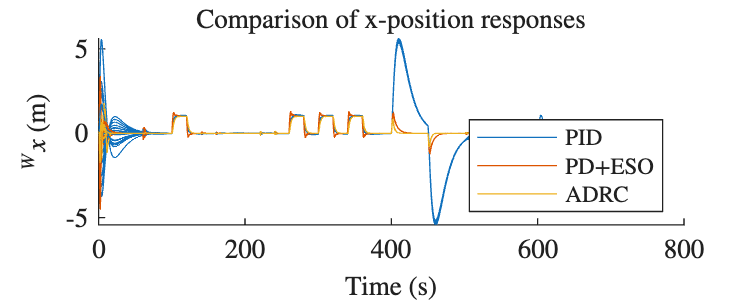

C = rgb2hex(orderedcolors('gem'));

% load("PositionSimOuts.mat")

figure, clf, hold on
title("Comparison of x-position responses")
ylabel("$^Wx$ (m)")
xlabel("Time (s)")
plot(PID.time{1,1}, PID.x{1,1},Color=C(1),DisplayName="PID")
plot(PDESO.time{1,1}, PDESO.x{1,1},Color=C(2),DisplayName="PD+ESO")
plot(ADRC.time{1,1}, ADRC.x{1,1},Color=C(3),DisplayName="ADRC")
for i=2:i_per_controller
    plot(PID.time{1,i}, PID.x{1,i},Color=C(1), HandleVisibility="off")
    plot(PDESO.time{1,i}, PDESO.x{1,i},Color=C(2), HandleVisibility="off")
    plot(ADRC.time{1,i}, ADRC.x{1,i},Color=C(3), HandleVisibility="off")
end
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)

set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

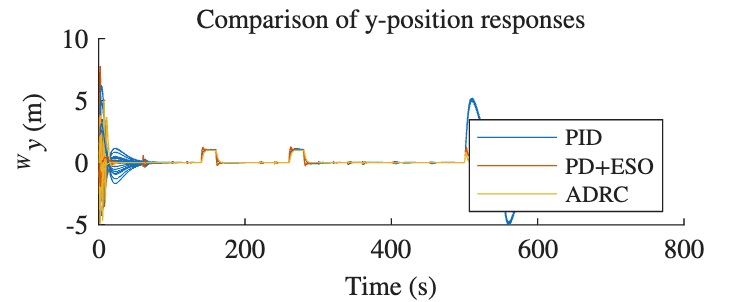


figure, clf, hold on
title("Comparison of y-position responses")
ylabel("$^Wy$ (m)")
xlabel("Time (s)")
plot(PID.time{1,1}, PID.y{1,1},Color=C(1),DisplayName="PID")
plot(PDESO.time{1,1}, PDESO.y{1,1},Color=C(2),DisplayName="PD+ESO")
plot(ADRC.time{1,1}, ADRC.y{1,1},Color=C(3),DisplayName="ADRC")
for i=2:i_per_controller
    plot(PID.time{1,i}, PID.y{1,i},Color=C(1), HandleVisibility="off")
    plot(PDESO.time{1,i}, PDESO.y{1,i},Color=C(2), HandleVisibility="off")
    plot(ADRC.time{1,i}, ADRC.y{1,i},Color=C(3), HandleVisibility="off")
end
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)

set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

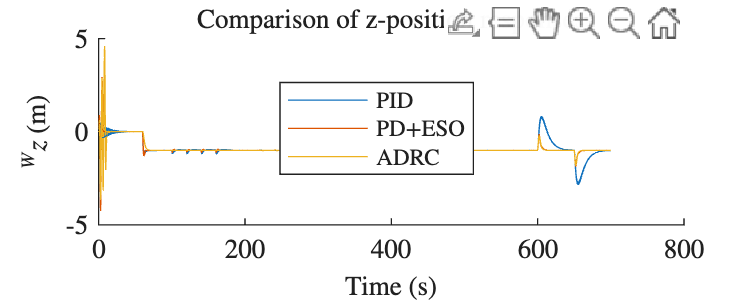


figure, clf, hold on
title("Comparison of z-position responses")
ylabel("$^Wz$ (m)")
xlabel("Time (s)")
plot(PID.time{1,1}, PID.z{1,1},Color=C(1),DisplayName="PID")
plot(PDESO.time{1,1}, PDESO.z{1,1},Color=C(2),DisplayName="PD+ESO")
plot(ADRC.time{1,1}, ADRC.z{1,1},Color=C(3),DisplayName="ADRC")
for i=2:i_per_controller
    plot(PID.time{1,i}, PID.z{1,i},Color=C(1), HandleVisibility="off")
    plot(PDESO.time{1,i}, PDESO.z{1,i},Color=C(2), HandleVisibility="off")
    plot(ADRC.time{1,i}, ADRC.z{1,i},Color=C(3), HandleVisibility="off")
end

set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

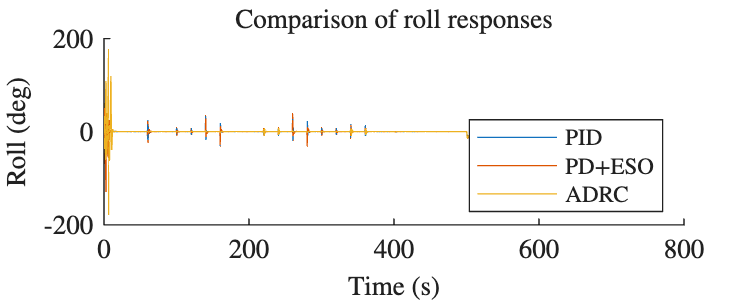


figure, clf, hold on
title("Comparison of roll responses")
ylabel("Roll (deg)")
xlabel("Time (s)")
plot(PID.time{1,1}, PID.roll{1,1},Color=C(1),DisplayName="PID")
plot(PDESO.time{1,1}, PDESO.roll{1,1},Color=C(2),DisplayName="PD+ESO")
plot(ADRC.time{1,1}, ADRC.roll{1,1},Color=C(3),DisplayName="ADRC")
for i=2:i_per_controller
    plot(PID.time{1,i}, PID.roll{1,i},Color=C(1), HandleVisibility="off")
    plot(PDESO.time{1,i}, PDESO.roll{1,i},Color=C(2), HandleVisibility="off")
    plot(ADRC.time{1,i}, ADRC.roll{1,i},Color=C(3), HandleVisibility="off")
end

set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

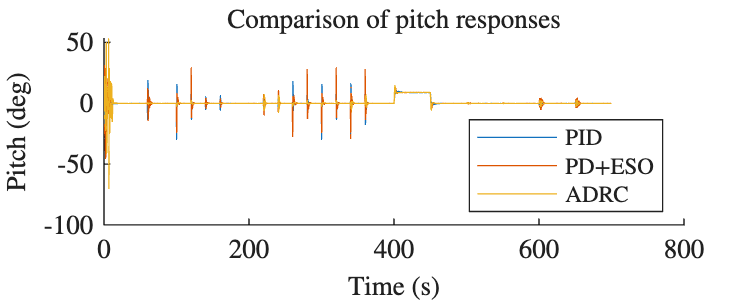


figure, clf, hold on
title("Comparison of pitch responses")
ylabel("Pitch (deg)")
xlabel("Time (s)")
plot(PID.time{1,1}, PID.pitch{1,1},Color=C(1),DisplayName="PID")
plot(PDESO.time{1,1}, PDESO.pitch{1,1},Color=C(2),DisplayName="PD+ESO")
plot(ADRC.time{1,1}, ADRC.pitch{1,1},Color=C(3),DisplayName="ADRC")
for i=2:i_per_controller
    plot(PID.time{1,i}, PID.pitch{1,i},Color=C(1), HandleVisibility="off")
    plot(PDESO.time{1,i}, PDESO.pitch{1,i},Color=C(2), HandleVisibility="off")
    plot(ADRC.time{1,i}, ADRC.pitch{1,i},Color=C(3), HandleVisibility="off")
end
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

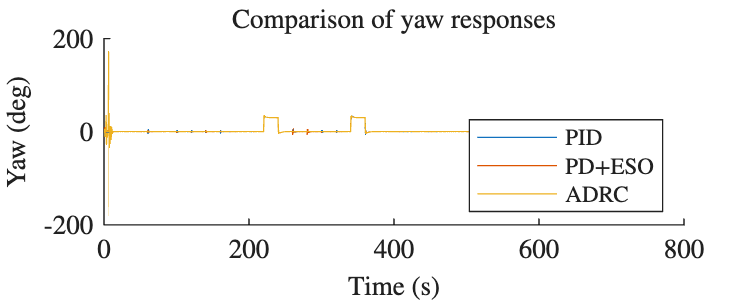



figure, clf, hold on
title("Comparison of yaw responses")
ylabel("Yaw (deg)")
xlabel("Time (s)")
plot(PID.time{1,1}, PID.yaw{1,1},Color=C(1),DisplayName="PID")
plot(PDESO.time{1,1}, PDESO.yaw{1,1},Color=C(2),DisplayName="PD+ESO")
plot(ADRC.time{1,1}, ADRC.yaw{1,1},Color=C(3),DisplayName="ADRC")
for i=2:i_per_controller
    plot(PID.time{1,i}, PID.yaw{1,i},Color=C(1), HandleVisibility="off")
    plot(PDESO.time{1,i}, PDESO.yaw{1,i},Color=C(2), HandleVisibility="off")
    plot(ADRC.time{1,i}, ADRC.yaw{1,i},Color=C(3), HandleVisibility="off")
end
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

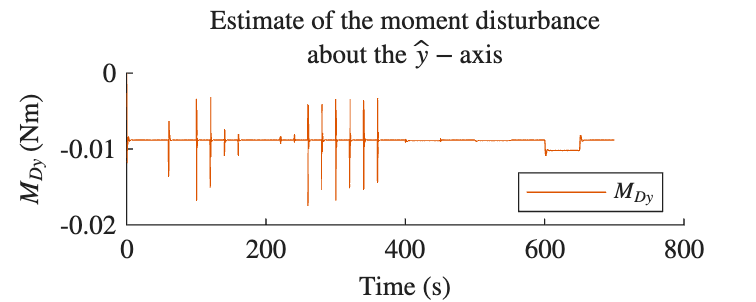


figure, clf, hold on
title({"Estimate of the moment disturbance", "about the $\hat{y}-$axis"})
ylabel("${M}_{Dy}$ (Nm)", Interpreter="latex")
xlabel("Time (s)")
% plot(PDESO.time{1,1}, PDESO.m_hat1{1,1},Color=C(1),DisplayName="$\hat{M}_x$")
plot(PDESO.time{1,1}, PDESO.m_hat2{1,1},Color=C(2),DisplayName="${M}_{Dy}$")
% plot(PDESO.time{1,1}, PDESO.m_hat3{1,1},Color=C(3),DisplayName="$\hat{M}_z$ PDESO")
for i=2:i_per_controller
    % plot(PDESO.time{1,i}, PDESO.m_hat1{1,i},Color=C(2), HandleVisibility="off")
    % plot(ADRC.time{1,i}, ADRC.m_hat1{1,i},Color=C(3), HandleVisibility="off")
end
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

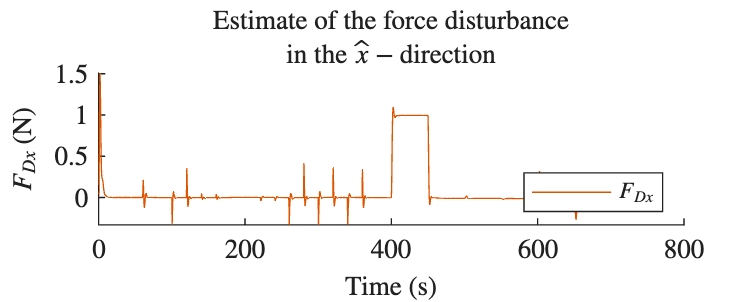


figure, clf, hold on
title({"Estimate of the force disturbance", "in the $\hat{x}-$direction"})
ylabel("${F}_{Dx}$ (N)", Interpreter="latex")
xlabel("Time (s)")
% plot(PDESO.time{1,1}, PDESO.m_hat1{1,1},Color=C(1),DisplayName="$\hat{M}_x$")
plot(PDESO.time{1,1}, PDESO.f_hat1{1,1},Color=C(2),DisplayName="$F_{Dx}$")
% plot(PDESO.time{1,1}, PDESO.m_hat3{1,1},Color=C(3),DisplayName="$\hat{M}_z$ PDESO")
for i=2:i_per_controller
    % plot(PDESO.time{1,i}, PDESO.m_hat1{1,i},Color=C(2), HandleVisibility="off")
    % plot(ADRC.time{1,i}, ADRC.m_hat1{1,i},Color=C(3), HandleVisibility="off")
end
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 10);
legend(Location="southeast", FontSize=8.5)
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off